N = 3 % number of data points

N = 3

I = 3 % dimension of data (dimension of each data point) (it is 2 but 

I = 3

% here setting it to 3 to account for weights biases)

% initial weights
initialWeights = [0 1 1]'; 

% Data points
xp1 = [1 2]; % red (class 0)
xp2 = [2 3]; % red (class 0)
xp3 = [5 4]; % blue (class 1)

% the N x I data matrix
X = [xp1; xp2; xp3];
X = [ones(1, N); X']' % adding ones to account for weight biases

X =      1     1     2
     1     2     3
     1     5     4



% Set class 1 = blue, class 0 = red
targets = [0 0 1]' % the N x 1 vector

targets =      0
     0
     1



proposalWidth = 0.1

proposalWidth = 0.1000

alpha = 0.01

alpha = 0.0100

eta = 0.01

eta = 0.0100

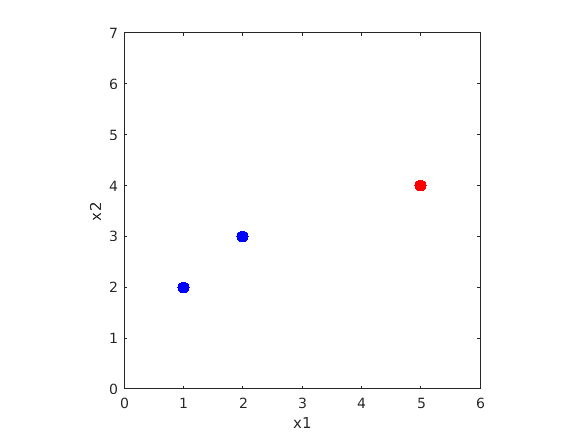

% Plot the data
figure(1); clf
plot(X(1:2, 2), X(1:2, 3), 'b.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(3, 2), X(3, 3), 'r.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 6]); ylim([0 7]); 
xlabel('x1'); ylabel('x2')
axis square

## Hand calculations for weights + decision boundary

wMAP = gradDescentBayesSingleNeuron(X, initialWeights, targets, eta, alpha)

## Initial probabilities of being in class 1

y = @(W) sigmoid(X * W)  %N x 1

y = function_handle with value:
    @(W)sigmoid(X*W)



y(initialWeights)

ans =     0.9526
    0.9933
    0.9999


## Targets predicted


y(wMAP)

ans =     0.0144
    0.0269
    0.9795
